## Lab 4.5

(a)

题目要求：

求满足（4.12）式的因果性LTI系统的频率响应H_1(jw)。定义向量b1和a1表示以(jw)的分子和分母的多项式。

分析：

分析可知H_1(jw)为

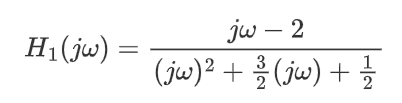

clear;
b1 = [1 -2];
a1 = [1 1.5 0.5];

(b)

题目要求：

使用residue函数计算部分分式展开，并重新组合这些项来确认H_1(jw)。

分析：

[r1, p1] = residue(b1, a1)

r1 =      6
    -5


p1 =    -1.0000
   -0.5000


分析可知H_1(jw)部分分式展开

对照residue函数获得的r1与p1可知，相同。

(c)

题目要求：

写出该系统的单位冲激响应h_1(t)，CTFT仅对绝对可积的连续时间信号存在，那么现在所得的h_1(t)是绝对可积的吗？

分析：

由上文，已知

由变换公式

可以得出h_1(t)

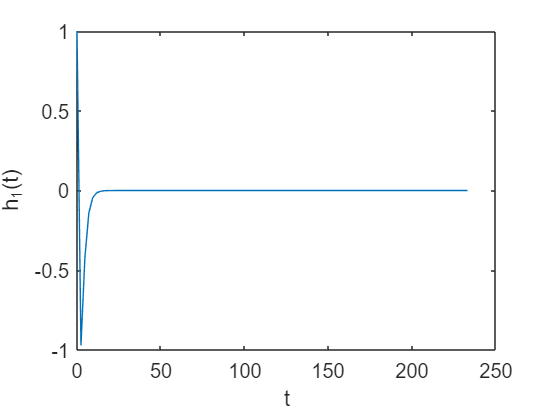

t = linspace(0,233);
h_1 = 6.*exp(-t) - 5.*exp(-0.5*t);

% 绘制h_1图像
figure
plot(t,h_1),xlabel('t'),ylabel('h_1(t)');

结论：由图像可知h_1(t)是绝对可积的。

(d)

题目要求：

定义向量b2和a2代表该系统频率响应H_2(jw)的分子和分母多项式。

分析：

b2 = [3 10 5];
a2 = [1 7 16 12];

(f)

题目要求：

使用residue函数得到r2和p2，求H_2(jw)的部分分式展开，并重组和式中的各项来证实得到了相同的H_2(jw)。

分析：

[r2, p2] = residue(b2, a2)

r2 =     2.0000
    1.0000
   -3.0000


p2 =    -3.0000
   -2.0000
   -2.0000


可知H_2(jw)部分分式展开

重组和式中的各项，得

由微分方程分析得知

可以得知，得到了相同的H_2(jw)。

(f)

题目要求：

用部分分式展开求得h_2(t)。

分析：

由变换公式

以及

可知

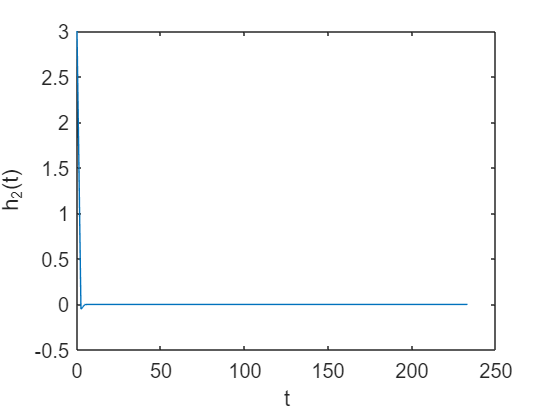

t = linspace(0,233);
h_2 = 2.*exp(-3.*t) + exp(-2.*t) - 3*t.*exp(-2.*t);

% 绘制h_2图像
figure
plot(t,h_2),xlabel('t'),ylabel('h_2(t)');

结论：由图像可知h_2(t)是绝对可积的。

（g)

题目要求：

定义向量b3与a3代表该系统函数H_3(jw)的分子和分母的多项式。

分析：

b3 = -4;
a3 = [1 0 -4];

(h)

题目要求：

用residue计算H_3(jw)的部分分式展开，并重组和式中的各项来证实得到了相同的H_3(jw)。

[r3, p3] = residue(b3, a3)

r3 =     -1
     1


p3 =     2.0000
   -2.0000


可知H_3(jw)部分分式展开

重组和式中的各项，得

由微分方程分析得知

可以得知，得到了相同的H_3(jw)。

(i)

题目要求：

求得单位冲激响应h_3(t)，因为假定系统稳定，所以h_3(t)必须可积，那么h_3(t)是因果的吗？

分析：

由变换公式

可知

当 t < 0 时，h_3(t) 不恒等于0，因此不是因果的。

结论：

h_3(t) 不是因果的。